# Steganography: Applications of Matrix Operations

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

Steganography is invisible ink for digital information. Linear algebra is used for encoding, embedding and decoding this information. Your audience needs to know that a message is there, but then simply applying a standard process will let them recover the information without any additional data, such as a key required in cryptography. 

With least significant bit steganography, we can embed digital information (text, images, data) in other forms of digital information. In this case, we're going to be hiding information inside images.

**Before you get started:**

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Linear Algebra Connections

Digital images are built out of matrices. This allows us to use the structures of linear algrebra to understand and implement image manipulation. There are two primary constraints that matrix arithmetic will impose on the images we work with:

- Matrices must be the same dimensions for addition/subtraction

- Matrices must have a matching number of rows (resp. columns) for multiplication

## Hiding a Black and White Image in a Color Image

  **Try**. Let's consider a simple mouse:

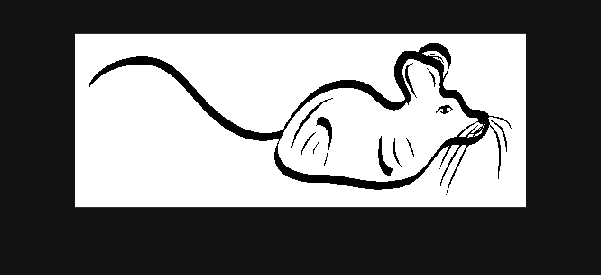

clf
load Mouse.mat mouse
imshow(mouse)

and a picture of some turkeys:

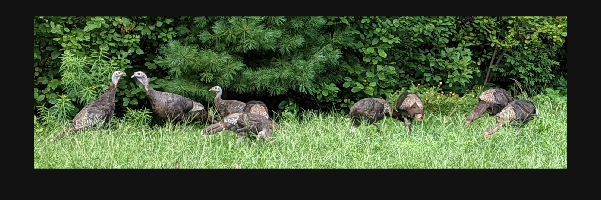

Turkeys = imread("turkeys1.jpg");
imshow(Turkeys)

 **Reflect**.

- How would you try to hide the mouse in among the turkeys?

- What challenges do you need to overcome?

### Comparable Size

Before we can combine the mouse and the turkeys, we need to consider the sizes of the matrices. 

SizeOfMouse = size(mouse)

SizeOfMouse =    192   500


SizeOfTurkeys = size(Turkeys)

SizeOfTurkeys =          562        1963           3


The steganographic algorithm we will be implementing involves matrix arithmetic. Because the sizes of these matrices do not match along any dimensions, we will need to do a bit of pre-processing to one or both of the images before we can begin discussing the steganography. In this section, we will investigate several of the options that we have for modifying the image matrices to have a comparable size.

#### Color space

The image of the turkeys is in RGB color space, one channel for red, one for green, and one for blue. For an introduction to image representation, see [Arrays.mlx](https://matlab.mathworks.com/open/github/v1?repo=MathWorks-Teaching-Resources/Fundamentals-of-Programming&project=FundamentalsofProgramming.prj&file=Arrays.mlx) in the [Fundamentals of Programming](https://www.mathworks.com/matlabcentral/fileexchange/103225-fundamentals-of-programming) module.

  **Try**. Explore the information contained in the 3D array `Turkeys`.

- Use powers of a permutation matrix to recombine the color channels

RotateMe = [0 1 0; 0 0 1; 1 0 0]

RotateMe =      0     1     0
     0     0     1
     1     0     0


channels = (1:3)'

channels =      1
     2
     3



channelSelect = RotateMe^(1)*channels

channelSelect =      2
     3
     1


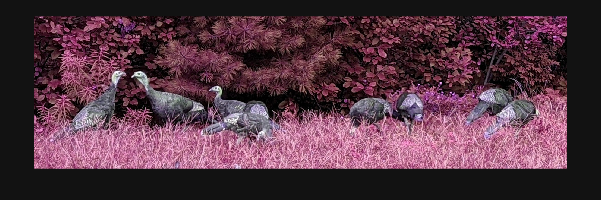


imshow(cat(3,Turkeys(:,:,channelSelect(1)),Turkeys(:,:,channelSelect(2)),Turkeys(:,:,channelSelect(3))))

We have two choices to force the matrix dimensions of `Turkeys` and `mouse` to match. One possibility is to extend `mouse` to exist in RGB space, or we can convert `Turkeys` into a grayscale image like `mouse`.

         2.  Average the values of the red, green, and blue channels to create a grayscale image.

MyGrayTurkeys = uint8(mean(Turkeys,3));

  **Pro-tip**. For details of the implementation of a MATLAB function,  

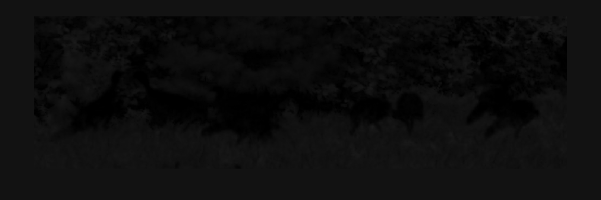

imshow(rgb2gray(Turkeys)-MyGrayTurkeys)

Many built-in functions are implemented in MATLAB and can be explored this way.

### Resizing Matrices 

There are a variety of ways that we could resize a matrix. For instance, we could 

A = [1 2; 3 4]

A =      1     2
     3     4


copySideways = [1 1 0 0; 0 0 1 1]

copySideways =      1     1     0     0
     0     0     1     1


A*copySideways

ans =      1     1     2     2
     3     3     4     4


  **Try**.

Create a matrix called `copyDown` that could be multiplied by `A` to create


$$\pmatrix{1 & 2 \cr 1 & 2 \cr 3 & 4 \cr 3 & 4}$$


Then use `copyDown`, `copySideways`, and `A` to create


$$\pmatrix{1 & 1 & 2 & 2 \cr 1 & 1 & 2 & 2 \cr 3 & 3 & 4 & 4 \cr 3 & 3 & 4 & 4 \cr}$$



% Solution
copyDown = [1 0; 1 0; 0 1; 0 1;]

copyDown =      1     0
     1     0
     0     1
     0     1


copyDown*A

ans =      1     2
     1     2
     3     4
     3     4


copyDown*A*copySideways

ans =      1     1     2     2
     1     1     2     2
     3     3     4     4
     3     3     4     4


% End Solution

 **Reflect**. 

- Can variations on `copyDown` and `copySideways` allow you to scale `mouse` to match `Turkeys`? Why or why not?

- When might you want to scale `Turkeys` to match `mouse?`

SizeOfTurkeys(1:2)./SizeOfMouse

ans =     2.9271    3.9260


#### Taking a subset of a matrix

  **Try**. Although the results might be uninteresting, or give away the fact that you have changed an image, there are times when simply taking a subset of a matrix can be useful:

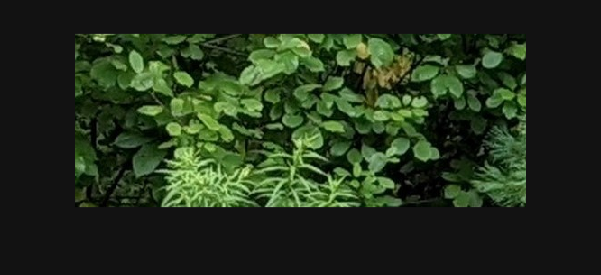

SmTurkeys = Turkeys(1:SizeOfMouse(1),1:SizeOfMouse(2),:);
imshow(SmTurkeys)

  **Pro-tip**. You could use the Image Viewer app to crop the larger image to approximately the desired size and region first, for instance.

#### Padding a matrix to a given size

In other cases, you may want to preserve the larger matrix and pad a smaller one to match the larger size.

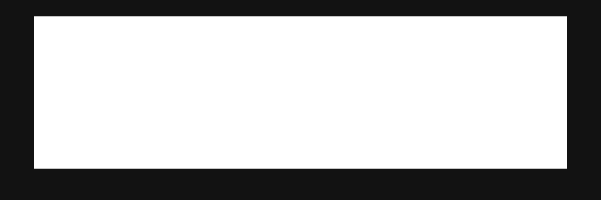

% Choose white or black padding
PaddedImage = ones(SizeOfTurkeys);
imshow(PaddedImage)

### Steganography: Hide the Mouse

The easiest path forward is to identify the largest dimensions needed, in this case `SizeOfTurkeys`.

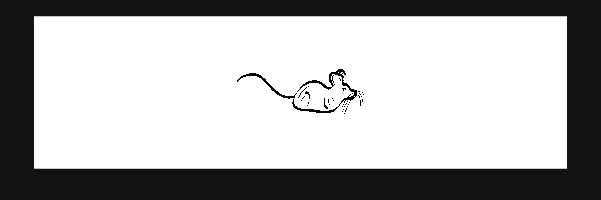

% Create a blank message of type uint8, which is the same type as Turkeys
MyMessage = uint8(ones(SizeOfTurkeys));

% Let's center the image we're planning to insert
WhereToStart = floor((SizeOfTurkeys(1:2)-SizeOfMouse)/2);
MyMessage(WhereToStart(1) + (1:SizeOfMouse(1)),WhereToStart(2) + (1:SizeOfMouse(2)),:) = repmat(mouse,1,1,3);

% Scale the values to range from 0-255 rather than 0-1
imshow(MyMessage*255)

unique(MyMessage)

ans = 2×1 uint8 column vector
   0
   1


Least significant digit steganography is an algorithm that replaces the least significant (binary) digit of our image with the binary representation of our message.  Our mouse was already binary, but we need to zero out the least significant digit of `Turkeys`. We can use the [`mod`](https://www.mathworks.com/help/matlab/ref/mod.html) function to identify this value and matrix arithmetic to remove it. Visual inspection should show an image that most humans cannot distinguish from the original `Turkeys`.

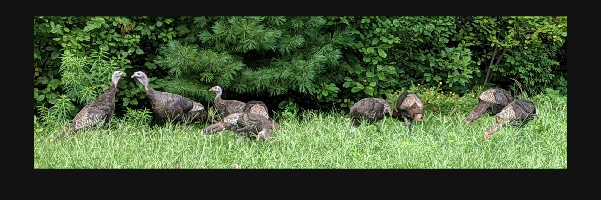

SimplifiedTurkeys = Turkeys - mod(Turkeys,2);
imshow(SimplifiedTurkeys)       

To hide the mouse in among the turkeys, we now just need to add the two matrices. 

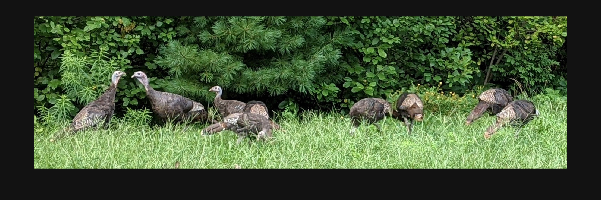

NewTurkeys = SimplifiedTurkeys + MyMessage;

imshow(NewTurkeys)

### Find the Mouse

We know that the difference `NewTurkeys-SimplifiedTurkeys` is the hidden image, but what if we only have a copy of `NewTurkeys` to work with? We know that we have replaced the least significant digit with our message, so by using `mod` we can recover the message.

% Identify the least significant digits in the encrypted image
LSDimg = mod(NewTurkeys,2);
% Rescale from [0,1] to the full range of values expected by imshow
imshow(LSDimg*255)

**Remember**: You can explore the documentation on the `mod` function by running the code

## Hiding Color Images Inside Color Images

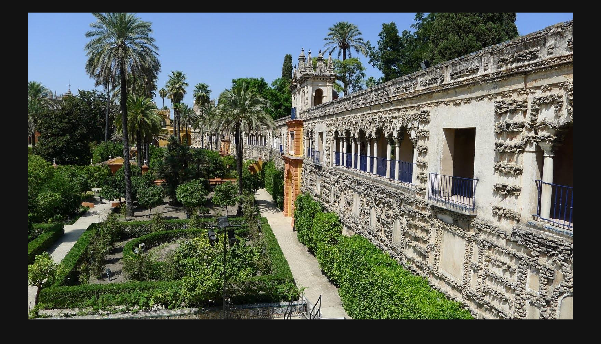

MyBaseImage = imread("sevilla.jpg");
imshow(MyBaseImage)

A full 8-bit color image is a lot to hide, so let's simplify our data a little. We can scale down to a 3-bit color image without too much loss of detail because we still have $8^3 = 512$ colors to work with. A 3-bit version of peppers.png can be calculated like so:

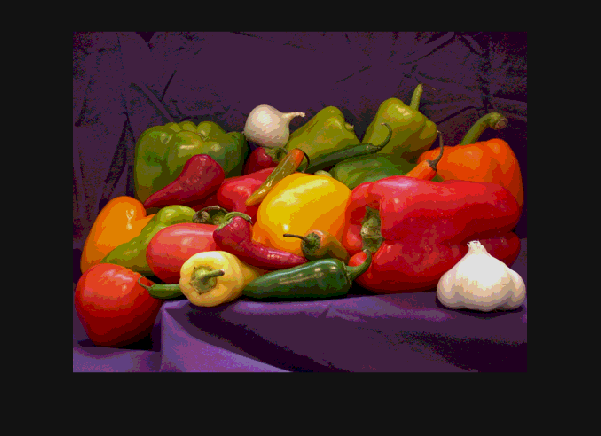

% Read the image file
MyCodeData = imread("peppers.png");
% MyCodeData = imread("Storms.png");
% Rescale from 0:255 to 0:7
MySmallData = uint8(floor(double(MyCodeData)/32));
imshow(MySmallData*32)

To embed this data as we hid the mouse we want to separate it into 1-bit channels:

MsgData1 = uint8(mod(MySmallData,8)>3);   % The most significant digit, 4's = 2^2 digit
MsgData2 = uint8(mod(MySmallData,4)>1);   % The 2's = 2^1 digit
MsgData3 = uint8(mod(MySmallData,2));     % The least significant digit, the 1's = 2^0 digit

 **Exercise 1. **Write code to check if the `baseImage` is large enough to contain `MsgData1, MsgData2,` and `MsgData3`. 


% Reference Solution to embed in the columns
[oM,oN,oC] = size(MyBaseImage);
[nM, nN, nC] = size(MySmallData);

if all([oM oN oC]>=[nM 3*nN nC])
    disp("This will work!")
else   % Extra flourish to handle cases that are too large by default.
    disp("This will not work at full resolution. Scaling down")
    ScaleFactor = floor(oN/3)/nN;
    disp("by a factor of "+ ScaleFactor)
    MySmallData = imresize(MySmallData,ScaleFactor);
    % [nM, nN, nC] = size(MySmallData);
    MsgData1 = uint8(mod(MySmallData,8)>3);   % The most significant digit, 4's = 2^2 digit
    MsgData2 = uint8(mod(MySmallData,4)>1);   % The 2's = 2^1 digit
    MsgData3 = uint8(mod(MySmallData,2));     % The least significant digit, the 1's = 2^0 digit
    % all([oM oN oC]>=[nM 3*nN nC])
end

This will work!



% Alternate solution to embed in the rows
[oM,oN,oC] = size(MyBaseImage);
[nM, nN, nC] = size(MySmallData);

if all([oM oN oC]>=[3*nM nN nC])
    disp("This will work in rows!")
else
    disp("This will not work in rows.")
end

This will not work in rows.



% Alternate solution based on msgData1,2,3
[oM,oN,oC] = size(MyBaseImage)

oM = 900

oN = 1600

oC = 3

totalMessage = cat(2,MsgData1,MsgData2,MsgData3);
[mdM,mdN,mdC] = size(totalMessage)

mdM = 384

mdN = 1536

mdC = 3


if all([mdM,mdN,mdC]<=[oM,oN,oC])
        disp("This will work in columns!")
end

This will work in columns!


% End Reference Solution

 **Exercise 2. **Write code that creates the message you want to hide. You may assume that the original image is in color. If you want more of a challenge, try the case that the original image is simply black and white as well.

% % Begin Reference Solution
MyMessage = zeros(size(MyBaseImage));

if floor(oN/nC) >= nN
    MyRowEnd = floor((oM-nM)/2);
    MyColEnd = floor(oN/3);
    if nC == 3
        MyMessage(MyRowEnd+(1:nM),(1:nN),:) = uint8(mod(MySmallData,8)>3);
        MyMessage(MyRowEnd+(1:nM),MyColEnd+(1:nN),:) = uint8(mod(MySmallData,4)>1);
        MyMessage(MyRowEnd+(1:nM),MyColEnd*2+(1:nN),:) = uint8(mod(MySmallData,2));
        disp("Embedded a color image.")
    else
        disp("Unexpected dimensions.")
    end
else
    disp("These dimensions are incompatible.")
end

Embedded a color image.


% % End Reference Solution

 **Exercise 3. **Create the encrypted image. Call your result `NewBaseImage`. Then use `imshow` to visualize the result. Is your message hidden?

This message can be embedded.


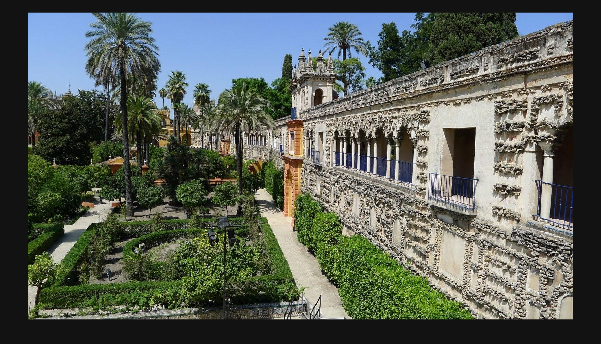

% % Sample Solution
if min([oM,oN,oC]-[nM, nN, nC],[],"all") >= 0
    disp("This message can be embedded.")

    NewBaseImage = MyBaseImage - mod(MyBaseImage,2) + uint8(MyMessage);

    imshow(NewBaseImage)
else
    disp("This message is too large for this base image.")
end

% % End Sample Solution

## Decryption!

To find a hidden image, we need to work in reverse. We cannot know the size of our hidden image so we have to work only with information present in the `NewBaseImage`. 

 **Exercise 4. **Write code that will reverse the operations you made in Exercises 1-3. 

[NumBaseRows,NumBaseColumns,~] = size(MyBaseImage);

First, determine the dimensions of the hidden image. Call them `HiddenRows` and `HiddenColumns`. Which one has been scaled down to make this image fit?

HiddenRows = NumBaseRows;
HiddenColumns = floor(NumBaseColumns/3);

Then find the least significant digit information from the hidden image.

UnencryptImage = mod(NewBaseImage,2);

Combine this information to create a full-color image 1/3 as big called `DecryptImage`. Remember that because we have scaled down the values by different amounts, we will need to scale them back up by different amounts as well:

`MsgData1` should get scaled up by `4*32 = 128`

`MsgData2` should get scaled up by `2*32 = 64 `

`MsgData3` should get scaled up by 1`*32 = 32 `

DecryptImage = UnencryptImage(:,1:HiddenColumns,:)*128+UnencryptImage(:,HiddenColumns+(1:HiddenColumns),:)*64+UnencryptImage(:,HiddenColumns*2+(1:HiddenColumns),:)*32;

Once you are done, visualize the result and slice off the unused border around the image by running the code below:

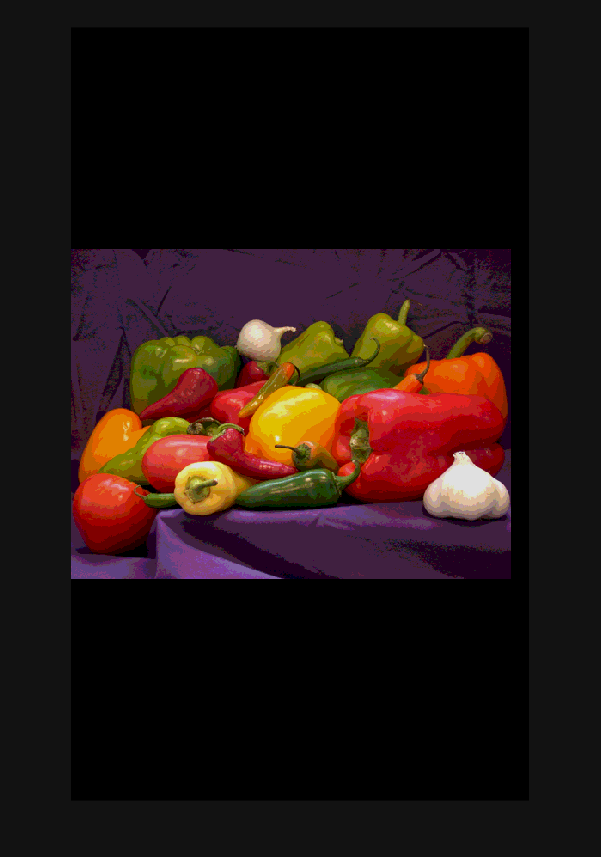

imshow(DecryptImage)

% In the region where there was no data to encrypt, the values of
% DecryptImage will all be 0. Let's find those so we can roughly
% focus on the area where there is information
CheckBorders = DecryptImage == 0;
CutValue = min(find(CheckBorders(:)==0,1,"first")-1,length(CheckBorders(:))-find(CheckBorders(:)==0,1,"last"))

CutValue = 258

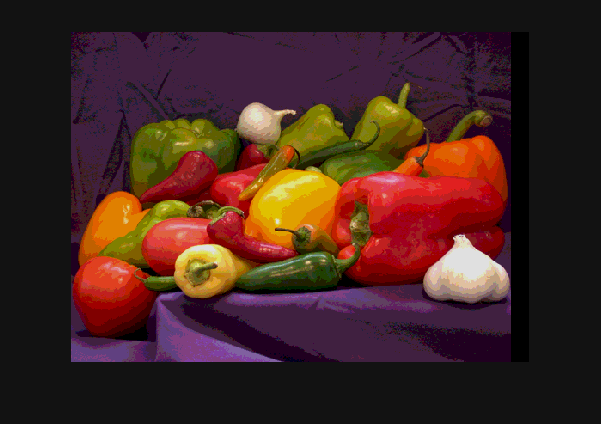

[a,~,~] = size(DecryptImage);

ResultImage = DecryptImage(CutValue+1:a-CutValue,:,:);
imshow(ResultImage)

 **Exercise 5. **

Locate the image hidden inside `ExerciseHidden.jpg`. The original version of `ExerciseHidden.jpg` is credited to NASA, ESA, CSA, STScI, Webb ERO Production Team, and the original hidden image is credited to NASA-GSFC, Adriana M. Gutierrez (CI Lab).

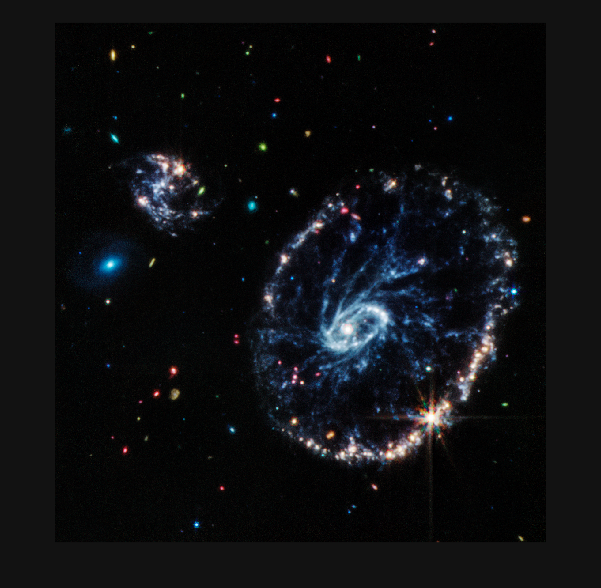

imshow("ExerciseHidden.jpg")

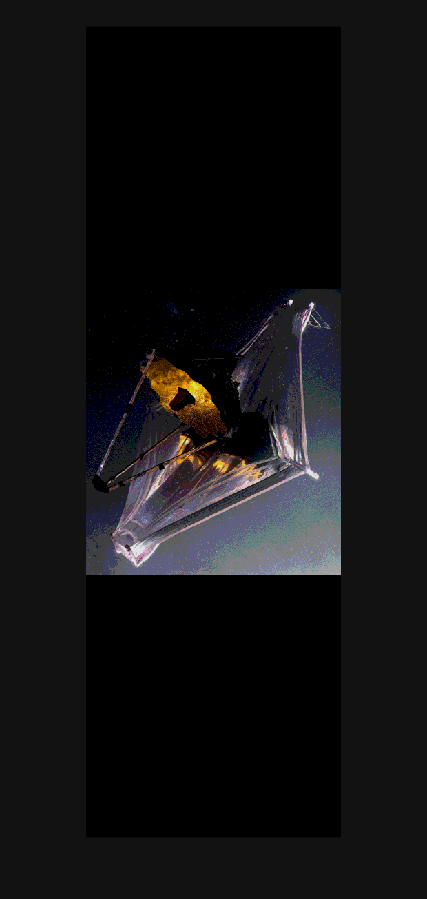

% % Solution
EncryptImage = imread("ExerciseHidden.jpg");
[oM,NumBaseColumns,oC] = size(EncryptImage);
HiddenColumns = floor(NumBaseColumns/3);
UnencryptImage = mod(EncryptImage,2);
DecryptSolution = UnencryptImage(:,1:HiddenColumns,:)*128+UnencryptImage(:,HiddenColumns+(1:HiddenColumns),:)*64+UnencryptImage(:,HiddenColumns*2+(1:HiddenColumns),:)*32;
imshow(DecryptSolution)

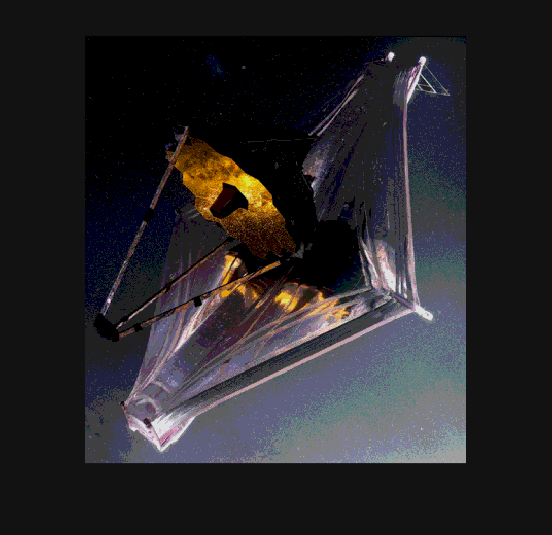

CheckBorders = DecryptSolution == 0;
CutValue = min(find(CheckBorders(:)==0,1,"first"),length(CheckBorders(:))-find(CheckBorders(:)==0,1,"last"));
[a,b,c] = size(DecryptSolution);
ResultImage = DecryptSolution(CutValue:a-CutValue,:,:);
imshow(ResultImage)

## Further Exploration

  **Try**. Load your own images and hide something inside them.

MyBaseImage = "";
MyMessage = "";

[⇦ Main Menu](matlab:open('MainMenu.mlx'))